% syms q_yogurt % [kg/h]
q_yogurt = 0:1:1000;

lambda_w = 2256.9; % [kJ/kg] 
k = 0.033925; %[W/m.K]
Ti = 25; % [C]
T_yogurt = Ti; % [C] 
T_f = 200; % [C]
cp_air = 1; % [kJ/kg.K]
rho_air = 1.29e-3; % [kg/L]
rho_yogurt = 1.03; % [kg/L]
N = 65000; % [rpm]
g = 9.8; % [m/s^2]
C_electricity = 0.0033; % [$/kwh]
x_w = 0.85;
D_p = 1e-2; % [m]
d_dryer = 0.1; % [m]
C_wage = 20; % [$/h]
life = 10; % [years]
r_production = 48.13*300; % [kg / year]

t_operation = r_production ./ (q_yogurt * (1 - x_w)); % [h / year]
t_residence = lambda_w * rho_yogurt * x_w * D_p ^ 2 * 1000/ ...
    (12 * k * (T_f - T_yogurt)); % [s]
q_air = 99 * (q_yogurt / rho_yogurt) * rho_air; % [kg/h]
h_dryer = (q_air / rho_air + q_yogurt / rho_yogurt) / 1000 / ...
    (pi * (d_dryer / 2) ^ 2) * t_residence / 3600; % [m]
P_heat = q_air * cp_air * (T_f - Ti) / 3600; % [kW]
d_atomizer = 0.13 * d_dryer; % [m]
P_atomizer = 0.0000000102 * (q_yogurt * 2.2 / 60) * (N * ...
    (d_atomizer * 3.28)) ^ 2 * 0.7457; % [kW]
P_pump = (q_yogurt ./ 3600)  .* g .* h_dryer; % [kW]

C_energy = (P_pump + P_atomizer + P_heat) .* t_operation .* ...
    C_electricity;  % [$ / year]
C_labor = t_operation * C_wage; % [$ / year]
C_variable = C_energy + C_labor; % [$ / year]

V_equip = pi * (d_dryer / 2) ^ 2 * h_dryer * 1000; % [L]
C_equip = 1.75 * (40409 + 1913 + 5249 + 3 * 991 + 3266 + ...
    1166 + 222 + 5975) * V_equip; % [$]
C_maintenance = 0.15 * C_equip; % [$ / year]
C_depreciation = (C_equip) / life; % [$ / year]
C_fixed = present_annual(C_equip, 0.2, life) + C_maintenance ...
    + C_depreciation; % [% / year]
C_annual = C_fixed + C_variable; % [$ / year]

plot(V_equip,C_fixed, 'LineWidth', 6)
hold on
plot(V_equip, C_variable, 'LineWidth', 6)
hold on
plot(V_equip, C_annual, 'LineWidth', 6)
ylim([0, 1e6])
xlim([0,6])
xlabel('Volume of Equipment, [L]', 'FontSize', 24)
ylabel('Annual Total Cost, [$/year]', 'FontSize', 24)


q_yogurt = 22.184;
t_operation = r_production ./ (q_yogurt * (1 - x_w)); % [h / year]
t_residence = lambda_w * rho_yogurt * x_w * D_p ^ 2 * 1000/ ...
    (12 * k * (T_f - T_yogurt)); % [s]
q_air = 99 * (q_yogurt / rho_yogurt) * rho_air; % [kg/h]
h_dryer = (q_air / rho_air + q_yogurt / rho_yogurt) / 1000 / ...
    (pi * (d_dryer / 2) ^ 2) * t_residence / 3600; % [m]
P_heat = q_air * cp_air * (T_f - Ti) / 3600; % [kW]
d_atomizer = 0.13 * d_dryer; % [m]
P_atomizer = 0.0000000102 * (q_yogurt * 2.2 / 60) * (N * ...
    (d_atomizer * 3.28)) ^ 2 * 0.7457; % [kW]
P_pump = (q_yogurt ./ 3600)  .* g .* h_dryer; % [kW]

C_energy = (P_pump + P_atomizer + P_heat) .* t_operation .* ...
    C_electricity;  % [$ / year]
C_labor = t_operation * C_wage; % [$ / year]
C_variable = C_energy + C_labor; % [$ / year]

V_equip = pi * (d_dryer / 2) ^ 2 * h_dryer * 1000; % [L]
C_equip = 1.75 * (40409 + 1913 + 5249 + 3 * 991 + 3266 + ...
    1166 + 222 + 5975) * V_equip; % [$]
C_maintenance = 0.15 * C_equip; % [$ / year]
C_depreciation = (C_equip) / life; % [$ / year]
C_fixed = present_annual(C_equip, 0.2, life) + C_maintenance ...
    + C_depreciation; % [% / year]
C_annual = C_fixed + C_variable; % [$ / year]

% fplot(C_fixed, [0,50])
% hold on
% fplot(C_variable, [0,50])
% hold on
% fplot(C_annual, [0,50])
% title('Optimization of Annual Cost')
% legend('fixed', 'variable', 'total')
% ylim([0, 1e6])
% xlabel('')
% ylabel('Annual Total Cost, [$/year]')

V_equip

V_equip = 1.6593

C_annual

C_annual = 1.7356e+05

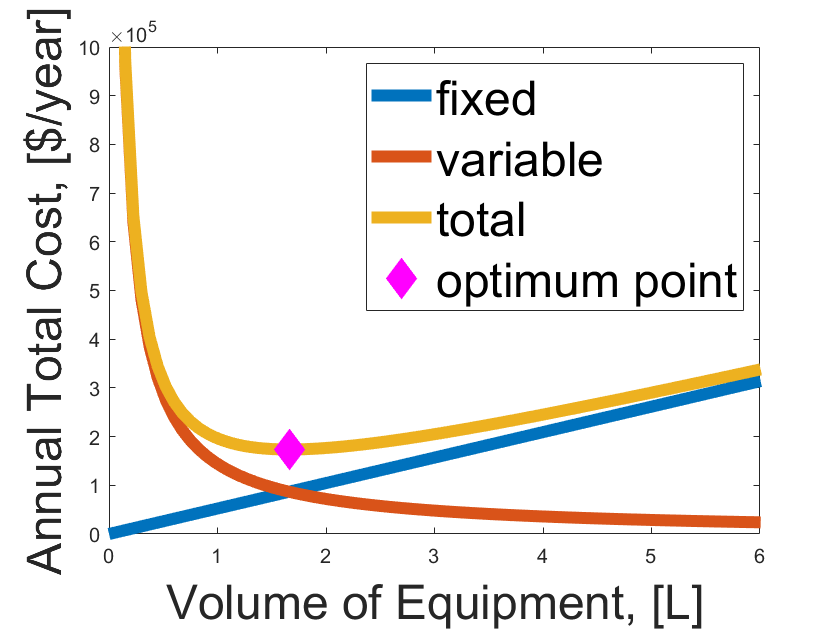


% g = diff(C_annual, q_yogurt);
% solve(g == 0, q_yogurt, 'MaxDegree', 4);
% opt_qyogurt = vpa(ans,6)
plot(V_equip, C_annual, 'd', 'MarkerSize', 15, 'MarkerEdgeColor','m', 'MarkerFaceColor','m')
title(' ')
legend({'fixed', 'variable', 'total', 'optimum point'}, 'FontSize', 24)
ylim([0, 1e6])
hold off



annual = double(subs(V_equip,opt_qyogurt(2)))

Undefined function or variable 'opt_qyogurt'.

height = double(subs(h_dryer,opt_qyogurt(2)))
equip_size = double(subs(V_equip, 10.58)) % L

function A = present_annual(P, i, N)
    % capital recovery
    A = P * (i * (1 + i) ^ N) / (((1 + i) ^ N) - 1);
end